# Figure 7F-G

correlation and boxplots for Olig2 GS and TA experiments

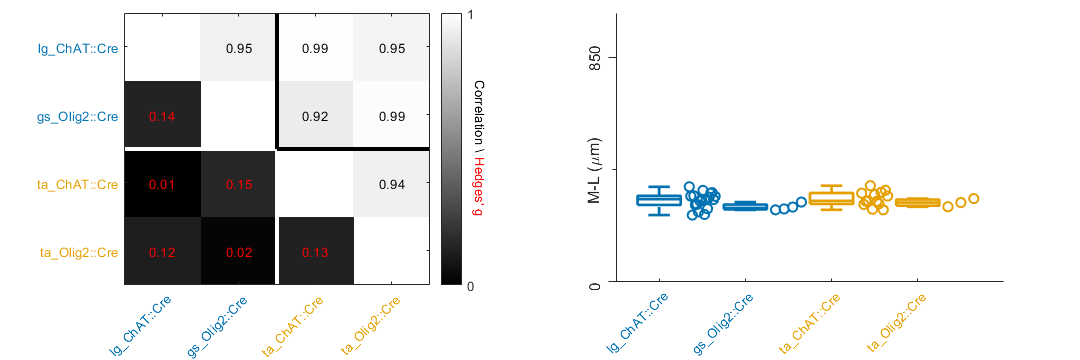

% plots correlation matrix for all experiments
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir

    dn = {[masterdir,'lg_chat\'],...
        [masterdir,'gs_olig2\'],...
        [masterdir,'ta_chat\'],...
        [masterdir,'ta_olig2\']};
    ndir = length(dn);


labels = {'\color[rgb]{0,0.4471,0.698}lg\_ChAT::Cre', '\color[rgb]{0,0.4471,0.698}gs\_Olig2::Cre'...
    ,'\color[rgb]{0.902,0.6235,0}ta\_ChAT::Cre','\color[rgb]{0.902,0.6235,0}ta\_Olig2::Cre'};

%%%%%%%%%%%%%%% switch to go straight to figure, rather than redoing
%%%%%%%%%%%%%%% calculations
readdata = 1;
%%%%%%%%%%%%%%%%

% figure settings
nr1 = 1;               % Number of rows in panel grid
nc1 = 2;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 0;  % if concat=1 concatenates all files in directory
numberson = 1; %if numberson = 1 adds numbers to the correlation table
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [5,5];          % kernel size
res = [20,20]; % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if readdata

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 
[allins,allmns] = poolfun(dn,1); % ins and mns have the same dimensions 


for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end


% color settings
firstcolor = [0, 114, 178]/255;  %blu = GS
secondcolor = [230, 159, 0]/255; %orange = TA
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
seconddark = [180/255, 100/255, 0]; %dark orange = TA excitatory

%allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for GS and TA
allcolor = vertcat(repmat(secondcolor,nfiles(1),1), repmat(seconddark,nfiles(2),1)); % for other pairs of muscles

ndir = length(dn);
ext = 'xlsx';

for i = 1:ndir
files_{i} = dir([dn{i},'*.',ext]);
end
gsins = [];
for i = 1:nfiles(1)
        gsname{i} = files_{1}(i).name;
        gsname{i} = extractBefore(gsname{i},'_n');
        gsname{i} = strrep(gsname{i},'gs','lg');
        gsname{i} = insertBefore(gsname{i}, 'lg','\color[rgb]{0,0.4471,0.698}'); %= [0, 114, 178]/255;  %blu = 2nd directory = GS
        gsins = vertcat(gsins,ins{1}{i});
end
tains = [];
for i = 1:nfiles(2)
        taname{i} = files_{2}(i).name;
        taname{i} = extractBefore(taname{i},'_n');
        taname{i} = insertBefore(taname{i}, 'ta','\color[rgb]{0.902,0.6235,0}'); % =[230, 159, 0]/255; %orange = 1st directory = TA
        tains = vertcat(tains,ins{2}{i});
end
names = horzcat(gsname, taname);
names = insertBefore(names,'_','\');


for i = 1:ndir
    for j = 1:nfiles(i)
       median_ml{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0,1));
    end
end

%%%%%%%%%%%%% Starts bootstrap calculations

% twisted code to keep directory grouping (as a cell array) and
% concatenating all dorsal ipsi coordinates into a matrix that can be read
% by bootstrap code (rows are animals, columns are coordinates, NaNs are
% all at the end)
temp = cell(1,ndir);
ins_d_ipsi = cell(1,ndir);
boot_mean = cell(1,ndir);
boot_sd = cell(1,ndir);
boot_size = cell(1,ndir);
p_boot = zeros(ndir,ndir);
boot_hedges_median = zeros(ndir,ndir);
boot_hedges = cell(1,ndir);
nruns = 5000;

for i = 1:ndir
    for j = 1:nfiles(i)
        temp{i}{j} = ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0 ,1); %selects x coordinates for neurons in the ipsi dorsal quaadrant
    end
    ins_d_ipsi{i} = (nanhcat(temp{i}{:}))'; %animals are now rows, coordinates are column 
    %(to accomodate for hierarchicla bootstrap code by Sam Sober). Index i
    %is the muscle/experiment/directory
end
% defines the size of bootstrap at the level of animal
num_trials = 1*max(size(ins_d_ipsi{2},2),size(ins_d_ipsi{1},2));
for i = 1:ndir
    [boot_mean{i}, boot_sd{i},boot_size{i}] = get_bootstrapped_stats(ins_d_ipsi{i},nruns,num_trials,'mean');
end

for i = 1:ndir
    for j = 1:ndir
        p_boot(i,j) = (get_direct_prob(boot_mean{i},boot_mean{j}));
        hh = boot_mean{i}-boot_mean{j};
        nx = boot_size{i}(1); %All boot  sizes are the same
        ny = boot_size{j}(1); %All boot  sizes are the same
        pooled_s = sqrt( ((nx-1)*boot_sd{i}.^2 + (ny-1)*boot_sd{j}.^2)/(nx+ny-2) );
        boot_hedges{i}{j} = hh./pooled_s;
        boot_hedges_median(i,j) = median(boot_hedges{i}{j}); 
    end
end

gck = gckernel();
setKernel(gck,ker);
setResd(gck,res);
junk = gck.convolve([allins{1}{1}(:,1)' ; allins{1}{1}(:,2)']); %intializes values of bins

% Method three suggested by Gary via email. All 3 give same

% method 1
for i = 1:ndir
        conv_result1{i} = gck.convolve ([allins{i}{1}(:,1)';allins{i}{1}(:,2)']);
end


% % Lines up the files from the two direcotries to give a single matrix
% for  i = 1:ndir
%     for j = 1:nfiles(i)
%         j+(i-1)*nfiles(ndir-1);
%         conv_result_all{j+(i-1)*nfiles(ndir-1)} =conv_result1{i};
%         conv_result_ml{j+(i-1)*nfiles(ndir-1)} =sum(conv_result1{i}{j},1);
%         ins_all{j+(i-1)*nfiles(ndir-1)} = ins{i}{j};
%     end
% end

ins_all_mat=[];
for i = 1:size(allins,2)
    ins_all_mat = nanhcat(ins_all_mat,allins{i}{1}(allins{i}{1}(:,2)>0 & allins{i}{1}(:,1)>0 ,1));
end

for i = 1: size(conv_result1,2)
    for j = 1:size(conv_result1,2)
       
     %CXYconv(i,j) = corr2(conv_result_all{i},conv_result_all{j}); % uses the mean as center of distributions
     CXYconv(i,j) = corr2median(conv_result1{i},conv_result1{j}); % uses the median as center of distributions
    % [HKS(i,j), pKS(i,j), KSstatistic] = kstest2(conv_result_ml{i}, conv_result_ml{j});  
     %[pperm(i,j), observeddifference, effectsize] = permutationTest(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1),1000);
    % [pranksum_x(i,j), Hranksum_x(i,j),ranksumstatistic_x(i,j)] = ranksum(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1));  
    
     
    end
end

else
end

f1 = figure;
%set(f1,'Position',[1 1 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(1,[0.2,0.12],[0.75,0.84]);
Panels.tweak(2,[0.1,0.11],[0.8,0.85]);


% correlation panel;
%hmap =heatmap(CXYHIST,'XDisplayLabels',names, 'YDisplayLabels',names, 'CellLabelColor','r');
h =1;
corr_fig = Panels.setPanel(h);

%define rectangular matrix. the 'skip varaible adds whites on the digaonal
%to separate Hedges and correlation
skip = 0;
frame = zeros(size(conv_result1,2),size(conv_result1,2)+skip);
frame_corr = frame+ horzcat(zeros(size(conv_result1,2),skip),triu(CXYconv));
frame_corr_hedges = frame_corr + horzcat(tril(boot_hedges_median),zeros(size(conv_result1,2),skip));

%defines colormap (0 is white, -1 and 1 are black)

bl_to_white = find(frame_corr_hedges==0);
frame_corr_hedges(bl_to_white)=1;
mapcorr = imagesc(abs(frame_corr_hedges),[0,1]);
hh = colormap(gray);
cmap = vertcat(hh,flipud(hh));
colormap(gray);

ax = gca;
 set (ax,'YTick',1:ndir,'YTickLabel',labels,'XTick',1:ndir,'XTickLabel',labels,...
     'XTickLabelRotation', 45);
ax.YAxis.FontSize = 10;
ax.XAxis.FontSize = 10;
hold on

if numberson % switches on and off the numbers on the correlation matrix
    CXYconv_off_diag = triu(CXYconv,1);
    %CXYconv_off_diag = CXYconv_off_diag(CXYconv_off_diag>0);
    textStrings = num2str(CXYconv_off_diag(CXYconv_off_diag>0), '%0.2f');       % Create strings from the matrix values eliminating off diagonal elements
    [x, y] = meshgrid(1:size(CXYconv,1));  % Create x and y coordinates for the strings
    xh_off_diag = triu(x,1); % extracts off diagonal elements
    yh_off_diag = triu(y,1);
    xhupper = xh_off_diag(xh_off_diag>0); %keeps only upper diagonal element values
    yhupper = yh_off_diag(yh_off_diag>0);
    hStrings = text(xhupper(:), yhupper(:), textStrings(:,1:end), ...  % Plot the strings
                'HorizontalAlignment', 'center');
else
end

if numberson % switches on and off the numbers on the Hedges matrix
    CXYconv_off_diag = tril(abs(frame_corr_hedges),-1);
    %CXYconv_off_diag = CXYconv_off_diag(CXYconv_off_diag>0);
    textStrings = num2str(CXYconv_off_diag(CXYconv_off_diag>0), '%0.2f');       % Create strings from the matrix values eliminating off diagonal elements
    [xh, yh] = meshgrid(1:size(frame_corr_hedges,1));  % Create x and y coordinates for the strings
    xh_off_diag = tril(xh,-1); % extracts off diagonal elements
    yh_off_diag = tril(yh,-1);
    xhupper = xh_off_diag(xh_off_diag>0); %keeps only upper diagonal element values
    yhupper = yh_off_diag(yh_off_diag>0);
    hStrings = text(xhupper(:), yhupper(:), textStrings(:,1:end), ...  % Plot the strings
                'HorizontalAlignment', 'center', 'Color',[1,0,0]);
else
end

cbcorr = colorbar;
set(cbcorr,'FontSize',10, 'Ticks',[0,1] );
cbcorr.Label.String = {'\color[rgb]{0,0,0}Correlation \\ \color[rgb]{1,0,0}Hedges'' g'};
cbcorr.Label.FontSize = 10;
cbcorr.Label.Rotation = -90;
cbcorr.Label.Position = [2.2879 0.5000 0];
%left bottom
ph = plot([ndir/2+0.5,ndir/2+0.5],[ndir/2-0.5,ndir+0.5],'w','LineWidth',3); %vertical
plot([1-0.5,ndir/2+0.5], [ndir/2+0.5,ndir/2+0.5],'w','LineWidth',3); %horizontal
%caxis([0,1]);
%top right
ph = plot([ndir/2+skip+0.5,ndir/2+skip+0.5],[1-0.5,ndir/2+0.5],'k','LineWidth',3); %vertical
plot([ndir/2+skip+0.5,ndir+skip+0.5], [ndir/2+0.5,ndir/2+0.5],'k','LineWidth',3); %horizontal
colormap(gray)
caxis([0,1]);



h =2;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml{1}', median_ml{2}', median_ml{3}', median_ml{4}'),'Color',[firstcolor;firstcolor;secondcolor;secondcolor]);
set(bp,{'linew'},{2})
ax3 = gca;
set(ax3,'XLim',[0.5,5],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTickLabel',labels,...
    'FontSize',10,'YTick', [0,0.5], 'YTickLabels',  [0,850],...
    'YTickLabelRotation', 90,'XTickLabelRotation', 45);
set(ax3.YLabel,'Interpreter','tex');
         ax3.YLabel.String = 'M-L (\mum)';
         ax3.YLabel.Position = [0.35 0.25];
         ax3.YAxis.FontSize = 11;
         ax3.YAxis.FontName = 'arial';
         ax3.YAxis.MinorTick = 'on';
         ax3.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax3.YAxis.TickDirection = 'out';
         ax3.YAxis.TickLength = [0.0200 .3250];
hold on
ps = dischart(nanhcat(median_ml{1}', median_ml{2}',median_ml{3}', median_ml{4}'),[1.5,2.5,3.5,4.5],0.3,[0.1],'','','o');
set(ps{1},'MarkerEdgeColor',firstcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',firstcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{3},'MarkerEdgeColor',secondcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{4},'MarkerEdgeColor',secondcolor,'LineWidth',1.5, 'MarkerSize',7);
box off




Panels.addPanels();